clear all
syms lambda rA rB R1 R2 R3 uA3 uB3 ;

r1=[3.42;0.473;4.01];
u31=[-0.856;-0.117;0.504];
r2=[-3.42;-0.473;-4.21];
u32=[0.856;0.117;0.504];
r3=[-10.14;-8.36;3.94];
u33=[-0.856;-0.117;-0.504];
r4=[-10.14;-8.36;-12.50];
u34=[-0.856;-0.117;-0.504];
r5=[7.69;-9.29;-4.28];
u35=[0.856;0.117;-0.504];
r6=[7.69;-9.29;12.16];
u36=[0.856;0.117;-0.504];
r7=[3.42;16.913;4.01];
u37=[-0.856;-0.117;0.504];

x1=[];
y1=[];
x2=[];
y2=[];
x3=[];
y3=[];
x4=[];
y4=[];
x5=[];
y5=[];
x6=[];
y6=[];
% center and direction of spheroids

hold on
axis([0 10 0 10]);
for R3=1:0.2:10 %离心率
    R1=5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    x1=[x1,R1];
    y1=[y1,R3];   
end

ans =    10.4600    1.0000    1.0002


ans =    10.2200    1.2000    1.0007


ans =     9.9800    1.4000    1.0009


ans =     9.7400    1.6000    1.0006


ans =     9.4900    1.8000    1.0016


ans =     9.2500    2.0000    1.0005


ans =     9.0000    2.2000    1.0007


ans =     8.7500    2.4000    1.0005


ans =     8.4900    2.6000    1.0017


ans =     8.2400    2.8000    1.0009


ans =     7.9900    3.0000    1.0000


ans =     7.7300    3.2000    1.0009


ans =     7.4800    3.4000    1.0004


ans =     7.2300    3.6000    1.0004


ans =     6.9800    3.8000    1.0012


ans =     6.7400    4.0000    1.0013


ans =     6.5100    4.2000    1.0012


ans =     6.2900    4.4000    1.0009


ans =     6.0800    4.6000    1.0007


ans =     5.8800    4.8000    1.0006


ans =     5.6900    5.0000    1.0005


ans =     5.5100    5.2000    1.0004


ans =     5.3400    5.4000    1.0001


ans =     5.1700    5.6000    1.0014


ans =     5.0100    5.8000    1.0020


ans =     4.8600    6.0000    1.0016


ans =     4.7200    6.2000    1.0000


ans =     4.5700    6.4000    1.0013


ans =     4.4300    6.6000    1.0008


ans =     4.2900    6.8000    1.0007


ans =     4.1500    7.0000    1.0008


ans =     4.0100    7.2000    1.0010


ans =     3.8700    7.4000    1.0010


ans =     3.7300    7.6000    1.0009


ans =     3.5900    7.8000    1.0006


ans =     3.4400    8.0000    1.0020


ans =     3.3000    8.2000    1.0009


ans =     3.1500    8.4000    1.0016


ans =     3.0000    8.6000    1.0017


ans =     2.8500    8.8000    1.0014


ans =     2.7000    9.0000    1.0005


ans =     2.5400    9.2000    1.0012


ans =     2.3800    9.4000    1.0014


ans =     2.2200    9.6000    1.0010


ans =     2.0600    9.8000    1.0001


ans =     1.8900   10.0000    1.0007



plot(x1,y1,'color',[221, 42, 22]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[238, 148, 138]/256, ...
    'DisplayName','1-2');

for R3=4:0.2:10 %离心率
    R1=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r5,R1,R3,u31,u35);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    [R1,R3,miu2]
    x2=[x2,R1];
    y2=[y2,R3]; 
end

ans =    10.7100    4.0000    1.0000


ans =     9.7000    4.2000    1.0003


ans =     9.0300    4.4000    1.0000


ans =     8.5400    4.6000    1.0005


ans = 1×3
    8.1700    4.8000    1.0009


ans = 1×3
    7.8800    5.0000    1.0014


ans = 1×3
    7.6500    5.2000    1.0014


ans = 1×3
    7.4600    5.4000    1.0016


ans = 1×3
    7.3100    5.6000    1.0002


ans = 1×3
    7.1700    5.8000    1.0014


ans = 1×3
    7.0600    6.0000    1.0006


ans = 1×3
    6.9600    6.2000    1.0008


ans = 1×3
    6.8700    6.4000    1.0016


ans = 1×3
    6.8000    6.6000    1.0004


ans = 1×3
    6.7300    6.8000    1.0010


ans = 1×3
    6.6700    7.0000    1.0011


ans = 1×3
    6.6200    7.2000    1.0003


ans = 1×3
    6.5700    7.4000    1.0008


ans = 1×3
    6.5200    7.6000    1.0024


ans = 1×3
    6.4900    7.8000    1.0001


ans = 1×3
    6.4500    8.0000    1.0012


ans = 1×3
    6.4200    8.2000    1.0005


ans = 1×3
    6.3900    8.4000    1.0005


ans = 1×3
    6.3600    8.6000    1.0012


ans = 1×3
    6.3300    8.8000    1.0025


ans = 1×3
    6.3100    9.0000    1.0016


ans = 1×3
    6.2900    9.2000    1.0011


ans = 1×3
    6.2700    9.4000    1.0011


ans = 1×3
    6.2500    9.6000    1.0015


ans = 1×3
    6.2300    9.8000    1.0022


ans = 1×3
    6.2200   10.0000    1.0005


 
plot(x2,y2,'color',[29, 50, 67]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[142, 152, 161]/256, ...
    'DisplayName','1-5');


for R3=1:0.2:10 %离心率
    R1=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r6,R1,R3,u31,u36);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    [R1,R3,miu2]
    x3=[x3,R1];
    y3=[y3,R3];  
end

ans = 1×3
   11.3200    1.0000    1.0002


ans = 1×3
    8.9500    1.2000    1.0006


ans = 1×3
    8.1100    1.4000    1.0011


ans = 1×3
    7.6800    1.6000    1.0016


ans = 1×3
    7.4300    1.8000    1.0004


ans = 1×3
    7.2600    2.0000    1.0009


ans = 1×3
    7.1400    2.2000    1.0017


ans = 1×3
    7.0600    2.4000    1.0005


ans = 1×3
    6.9900    2.6000    1.0020


ans = 1×3
    6.9400    2.8000    1.0021


ans = 1×3
    6.9000    3.0000    1.0024


ans = 1×3
    6.8700    3.2000    1.0020


ans = 1×3
    6.8500    3.4000    1.0004


ans = 1×3
    6.8200    3.6000    1.0027


ans = 1×3
    6.8100    3.8000    1.0005


ans = 1×3
    6.7900    4.0000    1.0019


ans = 1×3
    6.7800    4.2000    1.0010


ans = 1×3
    6.7700    4.4000    1.0006


ans = 1×3
    6.7600    4.6000    1.0007


ans = 1×3
    6.7500    4.8000    1.0011


ans = 1×3
    6.7400    5.0000    1.0019


ans = 1×3
    6.7300    5.2000    1.0029


ans = 1×3
    6.7300    5.4000    1.0011


ans = 1×3
    6.7200    5.6000    1.0025


ans = 1×3
    6.7200    5.8000    1.0012


ans = 1×3
    6.7100    6.0000    1.0028


ans = 1×3
    6.7100    6.2000    1.0017


ans = 1×3
    6.7100    6.4000    1.0007


ans = 1×3
    6.7000    6.6000    1.0027


ans = 1×3
    6.7000    6.8000    1.0019


ans = 1×3
    6.7000    7.0000    1.0011


ans = 1×3
    6.7000    7.2000    1.0004


ans = 1×3
    6.6900    7.4000    1.0027


ans = 1×3
    6.6900    7.6000    1.0021


ans = 1×3
    6.6900    7.8000    1.0015


ans = 1×3
    6.6900    8.0000    1.0010


ans = 1×3
    6.6900    8.2000    1.0005


ans = 1×3
    6.6900    8.4000    1.0001


ans = 1×3
    6.6800    8.6000    1.0027


ans = 1×3
    6.6800    8.8000    1.0023


ans = 1×3
    6.6800    9.0000    1.0019


ans = 1×3
    6.6800    9.2000    1.0016


ans = 1×3
    6.6800    9.4000    1.0013


ans = 1×3
    6.6800    9.6000    1.0010


ans = 1×3
    6.6800    9.8000    1.0007


ans = 1×3
    6.6800   10.0000    1.0004



plot(x3,y3,'color',[63, 125, 162]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[159, 190, 208]/256, ...
    'DisplayName','1-6');

for R3=1.4:0.2:10 %离心率
    R1=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r2,r3,R1,R3,u32,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r2,r3,R1,R3,u32,u33);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r2,r3,R1,R3,u32,u33);
    end
    [R1,R3,miu2]
    x4=[x4,R1];
    y4=[y4,R3];  
end

ans = 1×3
   18.1100    1.4000    1.0001


ans = 1×3
   10.9300    1.6000    1.0000


ans = 1×3
    9.2400    1.8000    1.0010


ans = 1×3
    8.4400    2.0000    1.0002


ans = 1×3
    7.9600    2.2000    1.0010


ans = 1×3
    7.6500    2.4000    1.0009


ans = 1×3
    7.4300    2.6000    1.0013


ans = 1×3
    7.2700    2.8000    1.0013


ans = 1×3
    7.1500    3.0000    1.0009


ans = 1×3
    7.0500    3.2000    1.0020


ans = 1×3
    6.9800    3.4000    1.0006


ans = 1×3
    6.9200    3.6000    1.0001


ans = 1×3
    6.8600    3.8000    1.0024


ans = 1×3
    6.8200    4.0000    1.0017


ans = 1×3
    6.7900    4.2000    1.0001


ans = 1×3
    6.7500    4.4000    1.0025


ans = 1×3
    6.7300    4.6000    1.0007


ans = 1×3
    6.7000    4.8000    1.0027


ans = 1×3
    6.6800    5.0000    1.0026


ans = 1×3
    6.6700    5.2000    1.0005


ans = 1×3
    6.6500    5.4000    1.0017


ans = 1×3
    6.6400    5.6000    1.0006


ans = 1×3
    6.6200    5.8000    1.0028


ans = 1×3
    6.6100    6.0000    1.0024


ans = 1×3
    6.6000    6.2000    1.0024


ans = 1×3
    6.5900    6.4000    1.0027


ans = 1×3
    6.5900    6.6000    1.0003


ans = 1×3
    6.5800    6.8000    1.0010


ans = 1×3
    6.5700    7.0000    1.0020


ans = 1×3
    6.5700    7.2000    1.0001


ans = 1×3
    6.5600    7.4000    1.0014


ans = 1×3
    6.5500    7.6000    1.0028


ans = 1×3
    6.5500    7.8000    1.0014


ans = 1×3
    6.5500    8.0000    1.0000


ans = 1×3
    6.5400    8.2000    1.0018


ans = 1×3
    6.5400    8.4000    1.0006


ans = 1×3
    6.5300    8.6000    1.0025


ans = 1×3
    6.5300    8.8000    1.0015


ans = 1×3
    6.5300    9.0000    1.0006


ans = 1×3
    6.5200    9.2000    1.0027


ans = 1×3
    6.5200    9.4000    1.0019


ans = 1×3
    6.5200    9.6000    1.0011


ans = 1×3
    6.5200    9.8000    1.0004


ans = 1×3
    6.5100   10.0000    1.0028



plot(x4,y4,'color',[191, 144, 0]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[223, 199, 127]/256, ...
    'DisplayName','2-3');

for R1=4.4:0.2:10 %离心率
    R3=6;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r2,r4,R1,R3,u32,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r2,r4,R1,R3,u32,u34);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r2,r4,R1,R3,u32,u34);
    end
    [R1,R3,miu2]
    x5=[x5,R1];
    y5=[y5,R3];  
end

ans = 1×3
    4.4000   10.9100    1.0004


ans = 1×3
    4.6000    9.7200    1.0006


ans = 1×3
    4.8000    8.9500    1.0003


ans = 1×3
    5.0000    8.4000    1.0004


ans = 1×3
    5.2000    7.9900    1.0003


ans = 1×3
    5.4000    7.6700    1.0004


ans = 1×3
    5.6000    7.4100    1.0011


ans = 1×3
    5.8000    7.2000    1.0013


ans = 1×3
    6.0000    7.0300    1.0007


ans = 1×3
    6.2000    6.8800    1.0013


ans = 1×3
    6.4000    6.7600    1.0002


ans = 1×3
    6.6000    6.6500    1.0005


ans = 1×3
    6.8000    6.5500    1.0016


ans = 1×3
    7.0000    6.4700    1.0009


ans = 1×3
    7.2000    6.4000    1.0001


ans = 1×3
    7.4000    6.3300    1.0011


ans = 1×3
    7.6000    6.2700    1.0014


ans = 1×3
    7.8000    6.2200    1.0007


ans = 1×3
    8.0000    6.1700    1.0013


ans = 1×3
    8.2000    6.1300    1.0005


ans = 1×3
    8.4000    6.0900    1.0006


ans = 1×3
    8.6000    6.0500    1.0017


ans = 1×3
    8.8000    6.0200    1.0009


ans = 1×3
    9.0000    5.9900    1.0008


ans = 1×3
    9.2000    5.9600    1.0014


ans = 1×3
    9.4000    5.9300    1.0025


ans = 1×3
    9.6000    5.9100    1.0014


ans = 1×3
    9.8000    5.8900    1.0008


ans = 1×3
   10.0000    5.8700    1.0006


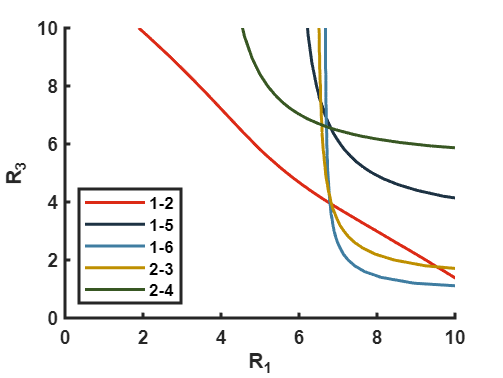


plot(x5,y5,'color',[56, 87, 35]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[155, 171, 145]/256, ...
    'DisplayName','2-4');

set(gca,'linewidth',1.5,'FontWeight','bold','FontName','arial');
xlabel('R_1','FontName','arial','FontWeight','bold'); 
ylabel('R_3','FontName','arial','FontWeight','bold');
legend('Location','southwest');
hold off

function miu2=cont(rA,rB,R1,R3,uA3,uB3)
    syms lambda
    rAB=rB-rA;
    e=R3/R1;
    x=(1-lambda)*(1-e^2);
    y=lambda*(1-e^2);
    D=(1-x)*(1-y)-x*y*(dot(uA3,uB3))^2;
    alpha=x*(1-y)/D;
    beta=y*(1-x)/D;
    gama=x*y*(dot(uA3,uB3))/D;
    I=eye(3);
    C=(I+alpha*(uA3*uA3.')+beta*(uB3*uB3.')+gama*((uA3*uB3.')+(uB3*uA3.')))/(R1^2);
    F=lambda*(1-lambda)*(rAB.'*C*rAB);
    fun=@(lambda) -eval(F);
    [~,fval]=fminbnd(fun,0,1);
    miu2=-fval;
end